clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 12 ; msize =8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MATLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Machs_mod = [1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
Machs_all = reshape( cat( 1, [Machs_mod], [Machs_mod] ), 1, [] );

t_ramp = 10; t_hold = 25;
t_all = zeros(size(Machs_all));
for i=1:((2*length(Machs_mod)))
    t_all(i)= floor(i/2)*t_hold+floor(i/2-1/2)*t_ramp;
end

t_sampling=t_all(2:2:end);
% Time 1, Cm 2, Cd 3, Cl 4, Cl(f) 5, Cl(r) 6
t_lines_access = (t_sampling./0.0005) % Read these rows

t_lines_access =        50000      120000      190000      260000      330000      400000      470000      540000      610000      680000      750000      820000      890000


% remove the /0.0005 if the following two lines are in the forceCoeffs
% file:
		%"writeControl    runTime;
		%writeInterval   1; //now every second"

Machs=transpose(Machs_mod);

%We want the 3rd (and 2nd and 4th columns)
format long
stag_1Ld=importdata('forceCoeffs1Ld.dat');
stag_075Ld=importdata('forceCoeffs075Ld.dat');
stag_05Ld=importdata('forceCoeffs05Ld.dat');
stag_025Ld=importdata('forceCoeffs025Ld.dat');
stag_zerod=importdata('forceCoeffszerod.dat');
stag_025Rd=importdata('forceCoeffs025Rd.dat');
stag_05Rd=importdata('forceCoeffs05Rd.dat');
stag_075Rd=importdata('forceCoeffs075Rd.dat');
stag_1Rd=importdata('forceCoeffs1Rd.dat');

Machs=flip(Machs)

Machs =    2.500000000000000
   2.400000000000000
   2.300000000000000
   2.200000000000000
   2.100000000000000
   2.000000000000000
   1.900000000000000
   1.800000000000000
   1.700000000000000
   1.600000000000000



% Drag

cd_stag_1Ld  =   (stag_1Ld.data(t_lines_access,3))  ./(Machs.^2);
cd_stag_075Ld=   (stag_075Ld.data(t_lines_access,3))./(Machs.^2);
cd_stag_05Ld =   (stag_05Ld.data(t_lines_access,3)) ./(Machs.^2);
cd_stag_025Ld=   (stag_025Ld.data(t_lines_access,3))./(Machs.^2);
cd_stag_zerod=   (stag_zerod.data(t_lines_access,3))./(Machs.^2);
cd_stag_025Rd=   (stag_025Rd.data(t_lines_access,3))./(Machs.^2);
cd_stag_05Rd =   (stag_05Rd.data(t_lines_access,3)) ./(Machs.^2);
cd_stag_075Rd=   (stag_075Rd.data(t_lines_access,3))./(Machs.^2);
cd_stag_1Rd  =   (stag_1Rd.data(t_lines_access,3))  ./(Machs.^2);

cd_stag_deccel = [cd_stag_1Ld,cd_stag_075Ld,cd_stag_05Ld,cd_stag_025Ld,cd_stag_zerod,cd_stag_025Rd,cd_stag_05Rd,cd_stag_075Rd,cd_stag_1Rd]

cd_stag_deccel =    0.029510560000000   0.026473056000000   0.015126312000000   0.011293843200000   0.014807108800000   0.011291051200000   0.015168539200000   0.026445184000000   0.029559600000000
   0.030210277777778   0.029256684027778   0.017724652777778   0.011141359375000   0.013776793402778   0.011144444444444   0.017781527777778   0.029227656250000   0.030261666666667
   0.030838695652174   0.032207466918715   0.020772381852552   0.011078931947070   0.012624332703214   0.011080173913043   0.020824593572779   0.032155689981096   0.030891890359168
   0.031355619834711   0.035358181818182   0.024376446280992   0.011412074380165   0.011298198347107   0.011423243801653   0.024433739669421   0.035324690082645   0.031385495867769
   0.031626802721088   0.038715124716553   0.028704126984127   0.014054682539683   0.009767848072562   0.014070714285714   0.028755056689342   0.038647709750567   0.031664331065760
   0.031387325000000   0.041097575000000   0.033799300000000   0.0164395150000


% Lift

cl_stag_1Ld  =   (stag_1Ld.data(t_lines_access,4))  ./(Machs.^2);
cl_stag_075Ld=   (stag_075Ld.data(t_lines_access,4))./(Machs.^2);
cl_stag_05Ld =   (stag_05Ld.data(t_lines_access,4)) ./(Machs.^2);
cl_stag_025Ld=   (stag_025Ld.data(t_lines_access,4))./(Machs.^2);
cl_stag_zerod=   (stag_zerod.data(t_lines_access,4))./(Machs.^2);
cl_stag_025Rd=   (stag_025Rd.data(t_lines_access,4))./(Machs.^2);
cl_stag_05Rd =   (stag_05Rd.data(t_lines_access,4)) ./(Machs.^2);
cl_stag_075Rd=   (stag_075Rd.data(t_lines_access,4))./(Machs.^2);
cl_stag_1Rd  =   (stag_1Rd.data(t_lines_access,4))  ./(Machs.^2);

cl_stag_deccel = [cl_stag_1Ld,cl_stag_075Ld,cl_stag_05Ld,cl_stag_025Ld,cl_stag_zerod,cl_stag_025Rd,cl_stag_05Rd,cl_stag_075Rd,cl_stag_1Rd]

cl_stag_deccel =   -0.069016912000000  -0.102170784000000  -0.093189872000000  -0.062554864000000  -0.000014394340800   0.062476880000000   0.092899648000000   0.102219168000000   0.069373488000000
  -0.051993229166667  -0.104019010416667  -0.100941597222222  -0.072706979166667  -0.000055848593750   0.072714131944444   0.100669375000000   0.104038784722222   0.052008732638889
  -0.031969508506616  -0.104617221172023  -0.108163686200378  -0.083147674858223   0.000070501058601   0.083052495274102   0.107832419659735   0.104518223062382   0.032066313799622
  -0.009157882231405  -0.103511219008264  -0.114682851239669  -0.093892417355372  -0.000030309938017   0.093836590909091   0.114417231404959   0.103556880165289   0.009167388429752
   0.016861802721088  -0.100897188208617  -0.120389433106576  -0.106734263038549   0.000043395918367   0.106834467120181   0.120250997732426   0.100564217687075  -0.016740995464853
   0.044180125000000  -0.084174650000000  -0.125158950000000  -0.1089346750000


M = cd_stag_deccel

M =    0.029510560000000   0.026473056000000   0.015126312000000   0.011293843200000   0.014807108800000   0.011291051200000   0.015168539200000   0.026445184000000   0.029559600000000
   0.030210277777778   0.029256684027778   0.017724652777778   0.011141359375000   0.013776793402778   0.011144444444444   0.017781527777778   0.029227656250000   0.030261666666667
   0.030838695652174   0.032207466918715   0.020772381852552   0.011078931947070   0.012624332703214   0.011080173913043   0.020824593572779   0.032155689981096   0.030891890359168
   0.031355619834711   0.035358181818182   0.024376446280992   0.011412074380165   0.011298198347107   0.011423243801653   0.024433739669421   0.035324690082645   0.031385495867769
   0.031626802721088   0.038715124716553   0.028704126984127   0.014054682539683   0.009767848072562   0.014070714285714   0.028755056689342   0.038647709750567   0.031664331065760
   0.031387325000000   0.041097575000000   0.033799300000000   0.016439515000000   0.007945

fmt = repmat(',%2.20f',1,size(M,2));
fmt = [fmt(2:end),'\n'];
[fid,msg] = fopen('cd_stag_deccel.csv', 'wt');
assert(fid>=3,msg)
fprintf(fid,fmt,M.')

ans =         2691


fclose(fid);

M = cl_stag_deccel

M =   -0.069016912000000  -0.102170784000000  -0.093189872000000  -0.062554864000000  -0.000014394340800   0.062476880000000   0.092899648000000   0.102219168000000   0.069373488000000
  -0.051993229166667  -0.104019010416667  -0.100941597222222  -0.072706979166667  -0.000055848593750   0.072714131944444   0.100669375000000   0.104038784722222   0.052008732638889
  -0.031969508506616  -0.104617221172023  -0.108163686200378  -0.083147674858223   0.000070501058601   0.083052495274102   0.107832419659735   0.104518223062382   0.032066313799622
  -0.009157882231405  -0.103511219008264  -0.114682851239669  -0.093892417355372  -0.000030309938017   0.093836590909091   0.114417231404959   0.103556880165289   0.009167388429752
   0.016861802721088  -0.100897188208617  -0.120389433106576  -0.106734263038549   0.000043395918367   0.106834467120181   0.120250997732426   0.100564217687075  -0.016740995464853
   0.044180125000000  -0.084174650000000  -0.125158950000000  -0.108934675000000  -0.000081

fmt = repmat(',%2.20f',1,size(M,2));
fmt = [fmt(2:end),'\n'];
[fid,msg] = fopen('cl_stag_deccel.csv', 'wt');
assert(fid>=3,msg)
fprintf(fid,fmt,M.')

ans =         2751


fclose(fid);


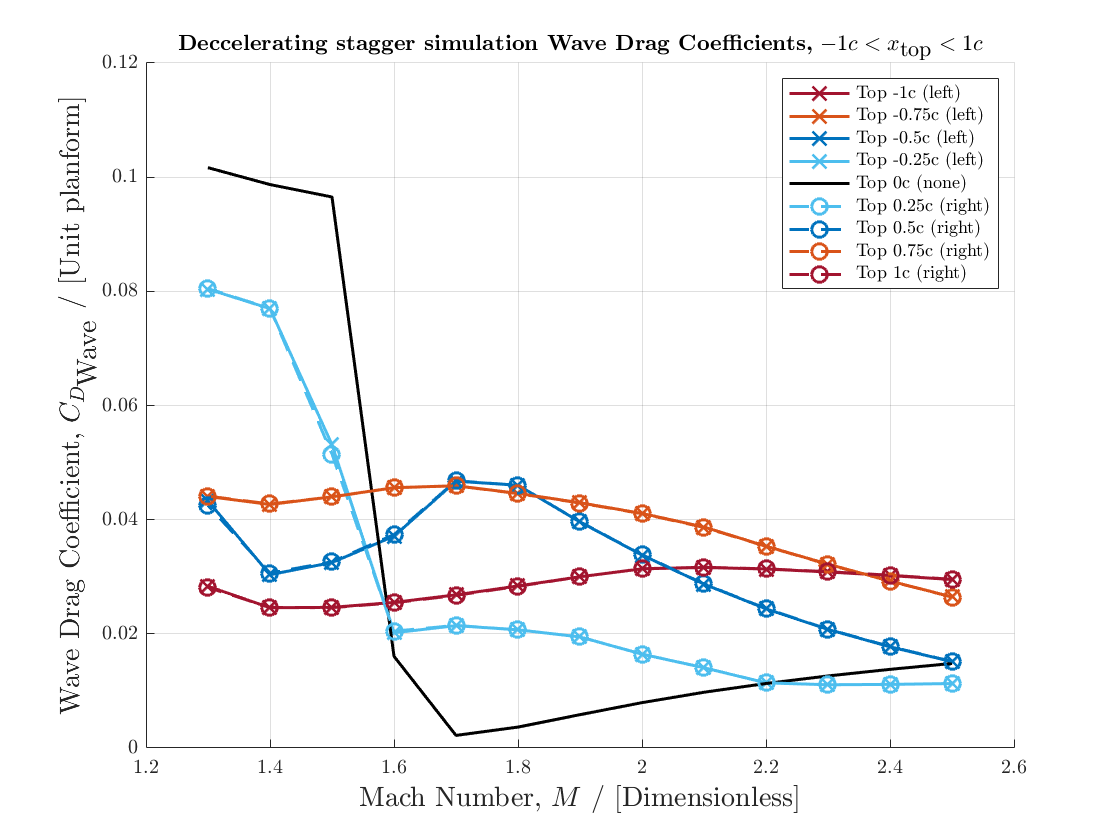

width = 1.5 ; % Line thickness
lsize = 14 ; tsize = 14 ; legsize = 12 ; msize =8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MATLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

load("cd_stag_deccel.mat")
load("cl_stag_deccel.mat")

Machs_mod = [1.3,1.4,1.5,1.6,1.7,1.8,1.9,2,2.1,2.2,2.3,2.4,2.5];
figure
hold on
plot(Machs,cd_stag_deccel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cd_stag_deccel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cd_stag_deccel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cd_stag_deccel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)

plot(Machs,cd_stag_deccel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machs,cd_stag_deccel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
plot(Machs,cd_stag_deccel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cd_stag_deccel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cd_stag_deccel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",red)

grid on; box off; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Wave Drag Coefficient, $C_{D_\textrm{Wave}}$ / [Unit planform]",'FontSize',lsize)
legend('Top -1c (left)','Top -0.75c (left)','Top -0.5c (left)','Top -0.25c (left)','Top 0c (none)','Top 0.25c (right)','Top 0.5c (right)','Top 0.75c (right)','Top 1c (right)')
title('\textbf{Deccelerating stagger simulation Wave Drag Coefficients,} $-1c<x_{\textrm{top}}<1c$')
hold off

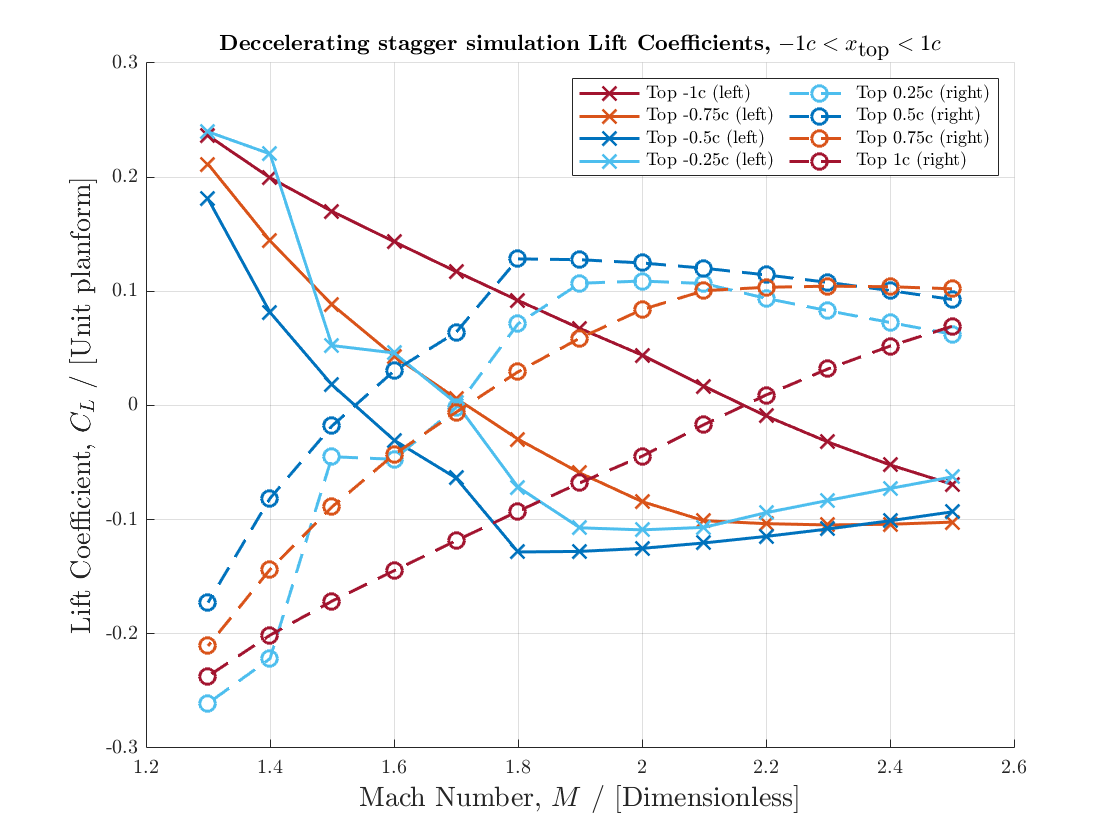


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure
hold on
plot(Machs,cl_stag_deccel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,cl_stag_deccel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cl_stag_deccel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cl_stag_deccel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)

plot(Machs,cl_stag_deccel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
plot(Machs,cl_stag_deccel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,cl_stag_deccel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,cl_stag_deccel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",red)

grid on; box off; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Lift Coefficient, $C_{L}$ / [Unit planform]",'FontSize',lsize)
legend('Top -1c (left)','Top -0.75c (left)','Top -0.5c (left)','Top -0.25c (left)','Top 0.25c (right)','Top 0.5c (right)','Top 0.75c (right)','Top 1c (right)','NumColumns',2)
title('\textbf{Deccelerating stagger simulation Lift Coefficients,} $-1c<x_{\textrm{top}}<1c$')
hold off

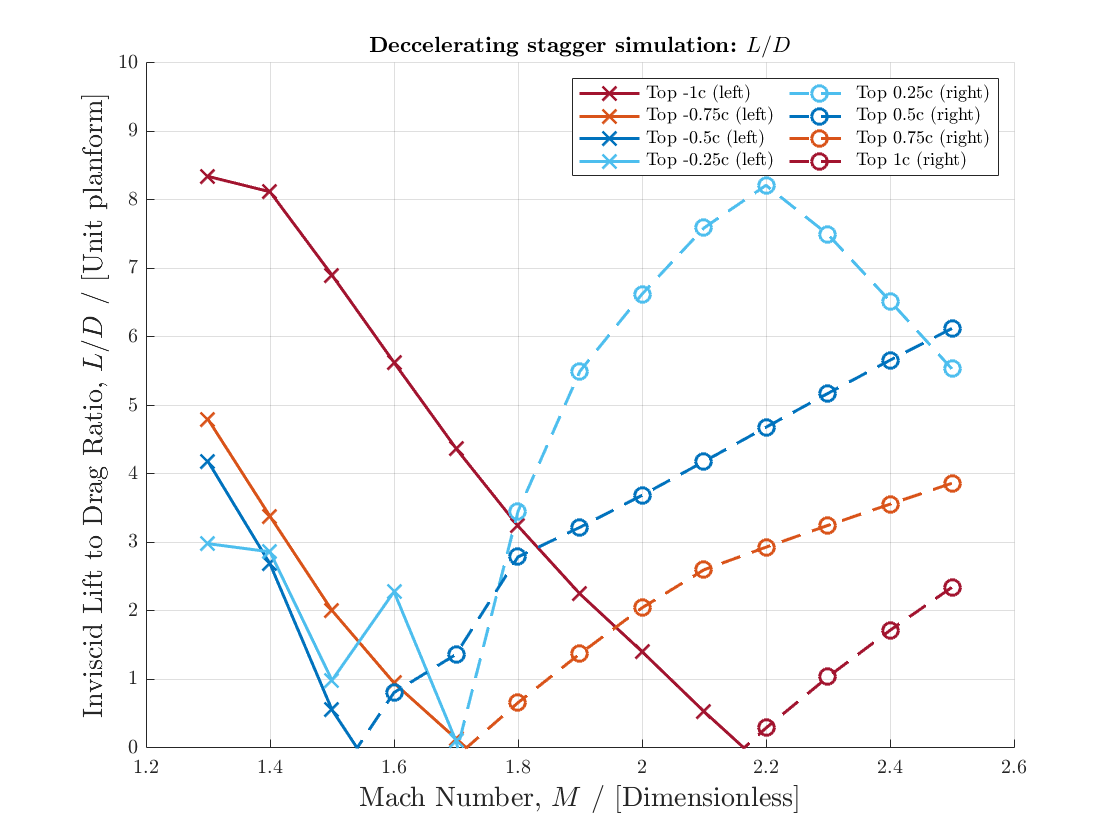


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
loverd_stag_deccel = cl_stag_deccel./cd_stag_deccel;

figure
hold on
plot(Machs,loverd_stag_deccel(:,1),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",red)
plot(Machs,loverd_stag_deccel(:,2),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,loverd_stag_deccel(:,3),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,loverd_stag_deccel(:,4),'x-',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)

%plot(Machs,loverd_stag_accel(:,5),'-',"LineWidth",1.5,"MarkerSize",msize,"Color",black)

plot(Machs,loverd_stag_deccel(:,6),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",lblue)
plot(Machs,loverd_stag_deccel(:,7),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
plot(Machs,loverd_stag_deccel(:,8),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(Machs,loverd_stag_deccel(:,9),'o--',"LineWidth",1.5,"MarkerSize",msize,"Color",red)

grid on; box off; hold on
%title("\textbf{Total Drag,} $C_{D_\textrm{Total}}$\textbf{, per unit chord for various biplane spacings}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Inviscid Lift to Drag Ratio, $L/D$ / [Unit planform]",'FontSize',lsize)
legend('Top -1c (left)','Top -0.75c (left)','Top -0.5c (left)','Top -0.25c (left)','Top 0.25c (right)','Top 0.5c (right)','Top 0.75c (right)','Top 1c (right)','NumColumns',2)
title('\textbf{Deccelerating stagger simulation:} $L/D$')
hold off
ylim([0 10])